# Project Team 12 - Data Analysis - Data Driven Marketing

## PROCESSING DATA

## Loading Data

% import file marketingdata
marketingdata = importfile('marketingdata.csv', 2, 2241);
% import file marketingdata theo t?ng column
[ID,Year_Birth,Education,Marital_Status,Income,Kidhome,Teenhome,Dt_Customer,Recency,MntWines,MntFruits,MntMeatProducts,MntFishProducts,MntSweetProducts,MntGoldProds,NumDealsPurchases,NumWebPurchases,NumCatalogPurchases,NumStorePurchases,NumWebVisitsMonth,AcceptedCmp3,AcceptedCmp4,AcceptedCmp5,AcceptedCmp1,AcceptedCmp2,Response,Complain,Country] = importfile1('marketingdata.csv',2, 2241);
% print data
disp(marketingdata);

     ID      Year_Birth     Education      Marital_Status      Income      Kidhome    Teenhome    Dt_Customer    Recency    MntWines    MntFruits    MntMeatProducts    MntFishProducts    MntSweetProducts    MntGoldProds    NumDealsPurchases    NumWebPurchases    NumCatalogPurchases    NumStorePurchases    NumWebVisitsMonth    AcceptedCmp3    AcceptedCmp4    AcceptedCmp5    AcceptedCmp1    AcceptedCmp2    Response    Complain    Country
    _____    __________    ____________

% shape of data
[row, column] = size(marketingdata);
fprintf('shape of data');

shape of data

disp([row, column]);

  Column 1

        2240

  Column 2

          28



%finding missing values in columns
total = sum(isnan(Income));
disp(total)

    24



% variables name of columns
variableNames = marketingdata.Properties.VariableNames;
disp(variableNames);

  Column 1

    'ID'

  Column 2

    'Year_Birth'

  Column 3

    'Education'

  Column 4

    'Marital_Status'

  Column 5

    'Income'

  Column 6

    'Kidhome'

  Column 7

    'Teenhome'

  Column 8

    'Dt_Customer'

  Column 9

    'Recency'

  Column 10

    'MntWines'

  Column 11

    'MntFruits'

  Column 12

    'MntMeatProducts'

  Column 13

    'MntFishProducts'

  Column 14

    'MntSweetProducts'

  Column 15

    'MntGoldProds'

  Column 16

    'NumDealsPurchases'

  Column 17

    'NumWebPurchases'

  Column 18

    'NumCatalogPurchases'

  Column 19

    'NumStorePurchases'

  Column 20

    'NumWebVisitsMonth'

  Column 21

    'AcceptedCmp3'

  Column 22

    'AcceptedCmp4'

  Column 23

    'AcceptedCmp5'

  Column 24

    'AcceptedCmp1'

  Column 25

    'AcceptedCmp2'

  Column 26

    'Response'

  Column 27

    'Complain'

  Column 28

    'Country'



summary(marketingdata);


Variables:

    ID: 2240x1 double
        Values:

            min            0
            median    5458.5
            max        11191

    Year_Birth: 2240x1 double
        Values:

            min       1893        
            median    1970        
            max       1996        

    Education: 2240x1 cell string

    Marital_Status: 2240x1 cell string

    Income: 2240x1 double
        Values:

            min        1730       
            median     51382      
            max        6.6667e+05 
            NaNs       24         

    Kidhome: 2240x1 double
        Values:

            min       0        
            median    0        
            max       2        

    Teenhome: 2240x1 double
        Values:

            min       0         
            median    0         
            max       2         

    Dt_Customer: 2240x1 da

## **Data types and data completeness**

- ID: Customer's Unique Identifier

- Year_Birth: Customer's Birth Year

- Education: Customer's education level

- Marital_Status: Customer's marital status

- Income: Customer's yearly household income

- Kidhome: Number of children in customer's household

- Teenhome: Number of teenagers in customer's household

- Dt_Customer: Date of customer's enrollment with the company

- Recency: Number of days since customer's last purchase

- MntWines: Amount spent on wine in the last 2 years

- MntFruits: Amount spent on fruits in the last 2 years

- MntMeatProducts: Amount spent on meat in the last 2 years

- MntFishProducts: Amount spent on fish in the last 2 years

- MntSweetProducts: Amount spent on sweets in the last 2 years

- MntGoldProds: Amount spent on gold in the last 2 years

- NumDealsPurchases: Number of purchases made with a discount

- NumWebPurchases: Number of purchases made through the company's web site

- NumCatalogPurchases: Number of purchases made using a catalogue

- NumStorePurchases: Number of purchases made directly in stores

- NumWebVisitsMonth: Number of visits to company's web site in the last month

- AcceptedCmp1: 1 if customer accepted the offer in the 1st campaign, 0 otherwise (Target variable)

- AcceptedCmp2: 1 if customer accepted the offer in the 2nd campaign, 0 otherwise (Target variable)

- AcceptedCmp3: 1 if customer accepted the offer in the 3rd campaign, 0 otherwise (Target variable)

## Feature Engineering

% create variable Age instead of varible Year_Birth
Age = 2021 - Year_Birth;
% create variable Spending
Spending = MntWines + MntFruits + MntMeatProducts + MntFishProducts + MntSweetProducts + MntGoldProds;
% create variable education_years thay cho education
Education = categorical(Education);
Marital_Status = categorical(Marital_Status);
Education_years = double(renamecats(Education,{'Basic','2n Cycle','Graduation','Master','PhD'},{'5','8','12','18','21'}));
% create variable numberChild = Kidhome + Teenhome
numberChild = Kidhome + Teenhome;
%create variable Marital_Situation
Marital_Situation =[];
for c = 1: length(Marital_Status)
     switch Marital_Status(c)
        case 'Married'
        Marital_Situation{c}= 'In Couple';
        case 'Single'
        Marital_Situation{c}= 'Alone';
        case 'Together'
        Marital_Situation{c} = 'In Coule';
        case 'YOLO'
        Marital_Situation{c} = 'Alone';
        case 'Widow'
        Marital_Situation{c} = 'Alone';
        case ' Divorced'
        Marital_Situation{c} = 'Alone';
        case 'Absurd'
        Marital_Situation{c} = 'Alone';
    end 
end
Marital_Situation = transpose(Marital_Situation);
%create variable HasChild
hasChild = [];
for c = 1:length(numberChild)
    if numberChild(c) == 0
        hasChild{c} = 'No';
    else 
        hasChild{c} = 'Yes';
    end
end
hasChild = transpose(hasChild);
% create data= (age, income, spending, marital_status,numberChild,Education_years)
data = table(ID, Age,Income,Spending,Marital_Situation,hasChild,Education_years);
disp(data);

     ID      Age      Income      Spending    Marital_Situation    hasChild    Education_years
    _____    ___    __________    ________    _________________    ________    _______________

     1826     51         84835    1190        'Alone'              'No'        3              
        1     60         57091     577        'Alone'              'No'        3              
    10476     63         67267     251        'In Couple'          'Yes'       3              
     1386     54         32474      11        'In Coule'           'Yes'       3              
     5371     32         21474      91        'Alone'              'Yes'       3              
     7348     63         71691    1192        'Alone'              'No'        5              
 

## Statistical Summary

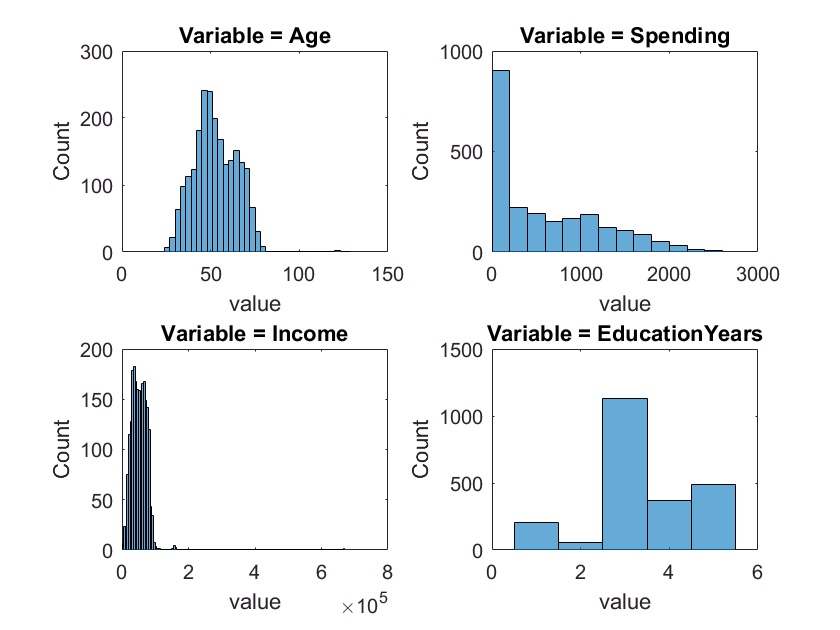

%describe data

% drawing plot
figure
subplot(2,2,1)
histogram(Age)
title('Variable = Age');
xlabel('value');
ylabel('Count');

subplot(2,2,2)
histogram(Spending)
title('Variable = Spending');
xlabel('value');
ylabel('Count');

subplot(2,2,3)
histogram(Income)
title('Variable = Income');
xlabel('value');
ylabel('Count');

subplot(2,2,4)
histogram(Education_years)
title('Variable = EducationYears');
xlabel('value');
ylabel('Count');

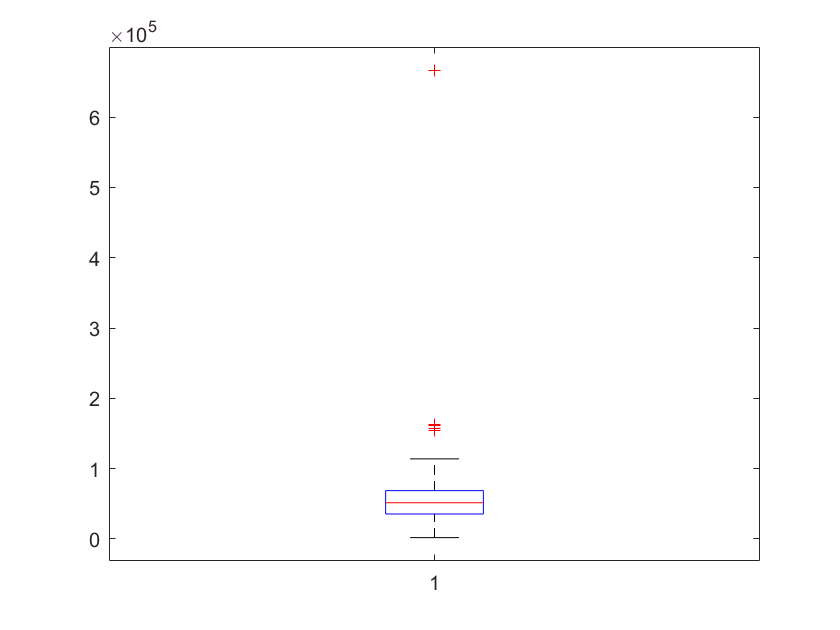

figure
boxplot(Income)

## Handing outliers

% draw boxplot for Age, Income , Spending, Education_years
figure

Row index exceeds table dimensions.


subplot(2,2,1)
boxplot(Age)
title('Variable = Age');
ylabel('Value');

subplot(2,2,2)
boxplot(Income)
title('Variable = Income');
ylabel('Value');

subplot(2,2,3)
boxplot(Spending)
title('Variable = Spending');
ylabel('Value');

subplot(2,2,4)
boxplot(Education_years);
title('Variable = EducationYears');
ylabel('Value');

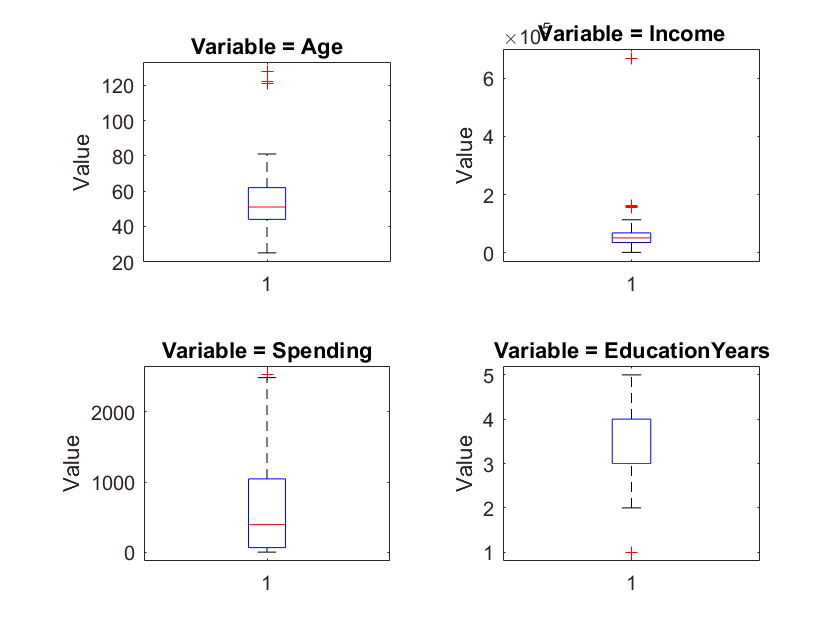

% remove rows which have Income > 600000- it's outliers values
dataset = data(~(data.Income>600000),:);
% combine dataset with Education volumn

data2 = table(ID, Education);
dataset = join(dataset,data2);
disp(dataset);

% split data in 7-3, 7(data train), 3(data test)
% cv = cvpartition(size(dataset,1),'HoldOut',0.3);
% datatrain = dataset(cv.training,:);
% datatest = dataset(cv.test,:);

     ID      Age      Income      Spending    Marital_Situation    hasChild    Education_years    Education 
    _____    ___    __________    ________    _________________    ________    _______________    __________

     1826     51         84835    1190        'Alone'              'No'        3                  Graduation
        1     60         57091     577        'Alone'              'No'        3                  Graduation
    10476     63         67267     251        'In Couple'          'Yes'       3                  Graduation
     1386     54         32474      11        'In Coule'           'Yes'       3                  Graduation
     5371     32         21474      91        'Alone'              'Yes' 

disp(length(dataset.Income));

        2239



## Handing missing values

dataset = dataset(~(isnan(dataset.Income)),:);
disp(dataset);

     ID      Age      Income      Spending    Marital_Situation    hasChild    Education_years    Education 
    _____    ___    __________    ________    _________________    ________    _______________    __________

     1826     51         84835    1190        'Alone'              'No'        3                  Graduation
        1     60         57091     577        'Alone'              'No'        3                  Graduation
    10476     63         67267     251        'In Couple'          'Yes'       3                  Graduation
     1386     54         32474      11        'In Coule'           'Yes'       3                  Graduation
     5371     32         21474      91        'Alone'              'Yes' 

disp(size(dataset));

  Column 1

        2215

  Column 2

           8



## VISUAL EXPLORATORY DATA ANALYSIS

## **Diploma distribution by income level**

nC=0; Bas=0; Gra=0; Mas=0; Ph=0; a1=0; b1=0; c1=0; d1=0; e1=0;
for c=1:length(dataset.Education)
    switch dataset.Education(c)
        case '2n Cycle'
        nC=nC+dataset.Income(c);
        a1=a1+1;
        case 'Basic'
        Bas=Bas+dataset.Income(c);
        b1=b1+1;
        case 'Graduation'
        Gra=Gra+dataset.Income(c);
        c1=c1+1;
        case 'Master'
        Mas=Mas+dataset.Income(c);
        d1=d1+1;
        case 'PhD'
        Ph=Ph+dataset.Income(c);
        e1=e1+1;
    end
end
Y = [nC/a1 Bas/b1 Gra/c1 Mas/d1 Ph/e1];
[y_sorted, y_order] = sort(Y,'ascend');
X = {'2n Cycle' 'Basic' 'Graduation' 'Master' 'PhD'};
x_order=X(y_order);
% X = categorical(x_order);
% X = reordercats(X,x_order);

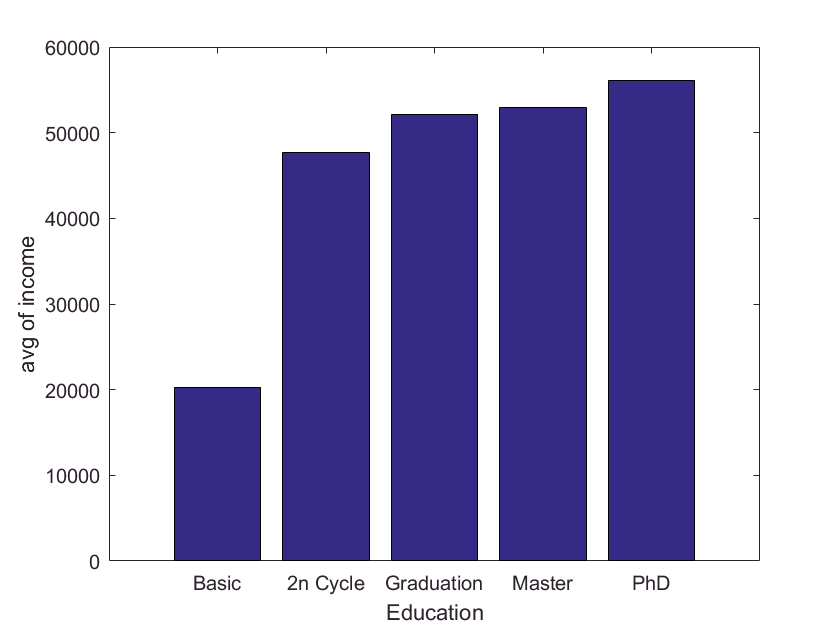

figure
bar(y_sorted);
set(gca,'xticklabel',x_order);
ylabel('avg of income');
xlabel('Education');
set(gca, 'YTickLabel', num2cell(get(gca, 'YTick')))

## **Spending by Income**

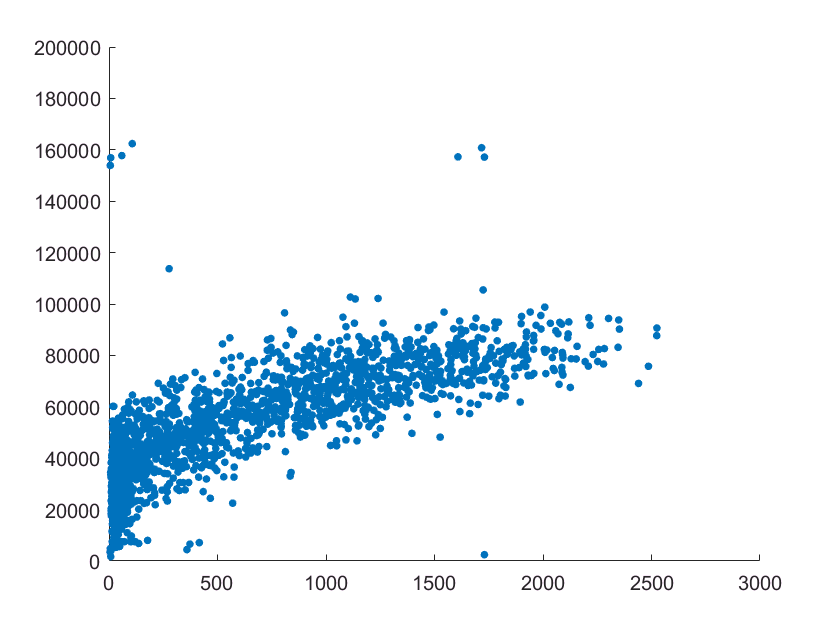

scatter(dataset.Spending,dataset.Income,15,'filled');
ylim([0 200000])
set(gca, 'YTickLabel', num2cell(get(gca, 'YTick')))

**Diploma distribution by marital situation**